# Histogram Matching

Histogram matching is useful when you are batch processing many images and want to apply a common threshold. This allows you to account for differences in intensity peaks while still avoiding the time-consuming process of calculating a new threshold for each image.

In this problem, you will predetermine a threshold value and use this threshold and histogram matching to segment a new crack image.

You will determine a reference threshold value based on the following image, "`refImg`" (00004.jpg from the Concrete Crack dataset)

And apply this threshold to segment a new image, "`newImg`" (00143.jpg from the concrete crack dataset), with and without histogram matching.

Write code that will:

- Determine the reference threshold value from `refImg`.

- Use this threshold to segment `newImg` without histogram matching. Save the results as `newImgBW`. You do not need to invert your mask (the crack should be dark).

- Match `newImg`'s histogram to `refImg`'s histogram. Then use the reference threshold to segment the histogram-matched crack image. Save the results as m`atchImgBW`. You do not need to invert your mask (the crack should be dark).

Consider your results. Which segmentation is more accurate? Noisier? If you were detecting cracks to identify areas of a dam that need repair, would the histogram-matched segmentation be sufficient? Share your thoughts on the forums.

refImg = im2gray(imread("00004.jpg"));
newImg = im2gray(imread("00143.jpg"));

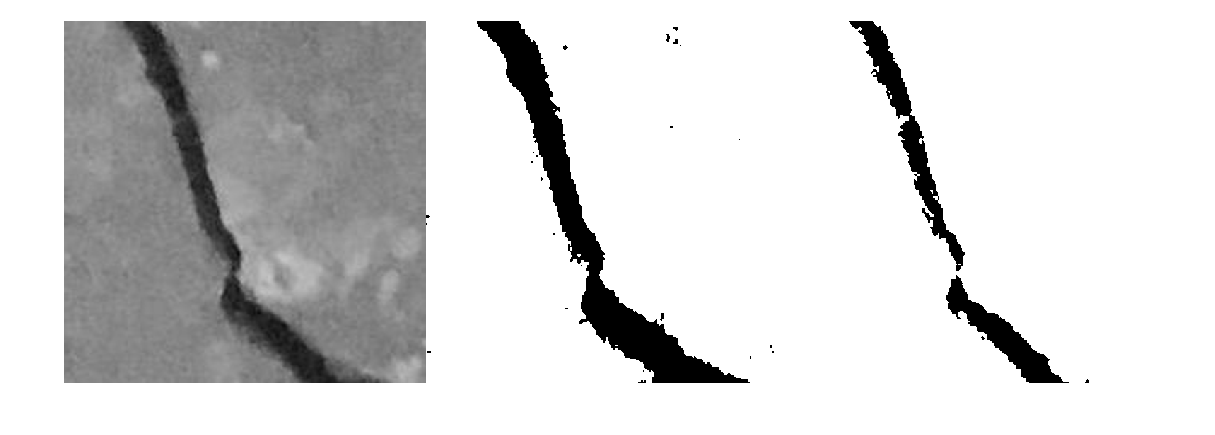

refTh = graythresh(refImg);
newImgBW = imbinarize(newImg, refTh);
matchImg = imhistmatch(newImg, refImg);
matchImgBW = imbinarize(matchImg, refTh);
montage({newImg, newImgBW, matchImgBW}, "Size", [1 3])